## Example: Running Multiple Optimization 

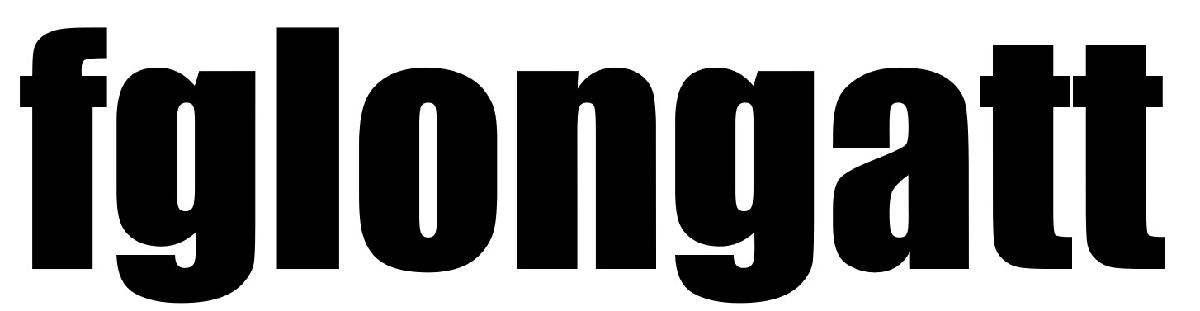  Prof F Gonzalez-Longatt, [fglongatt@fglongatt.org](http://fglongatt@fglongatt.org) 

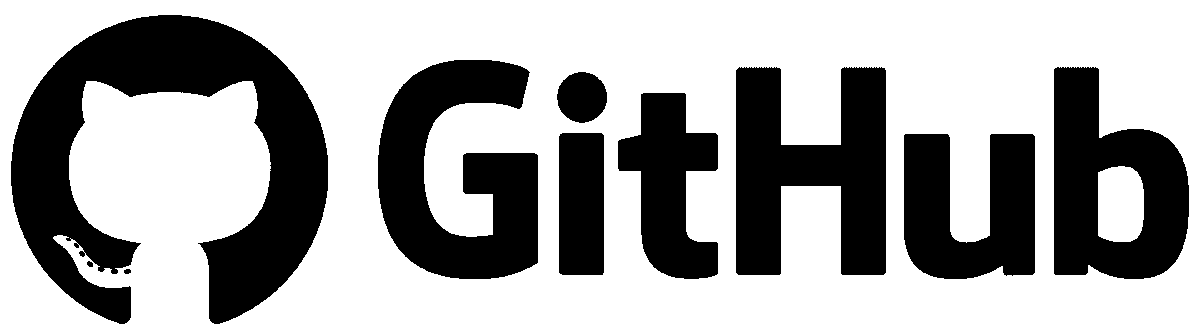 [https://github.com/fglongatt](https://github.com/fglongatt) 

In a system where transmission losses are negligible, the load of 1500 MW is supplied from two generations G1 and G2. The costs of generation are given by:


$$C_1 \left(P_1 \right)=10P_1 +{0\ldotp 008P}_1^2$$



$$C_2 \left(P_2 \right)=8P_2 +0\ldotp 009P_2^2$$


The units are subject to the following inequality constraints:


$$100\le P_1 \le 600$$



$$400\le P_2 \le 1000$$


Consider a 24-hour demand profile defined by the following plot:

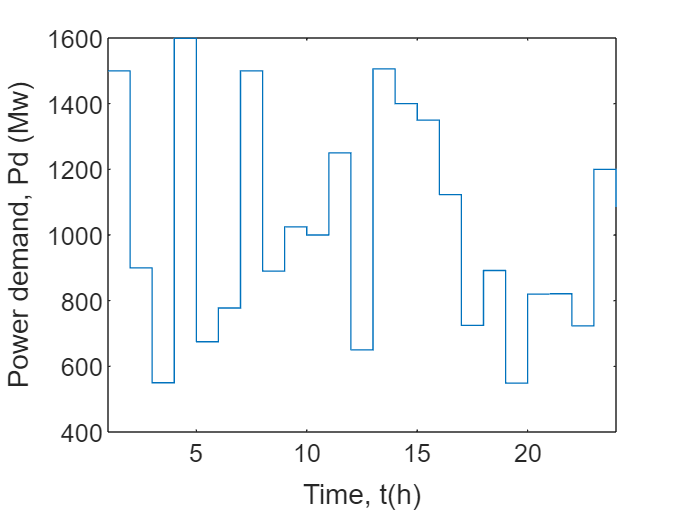

Pd = [1500 900 550 1599 675 777.777 1500 890 1025 1000 ...
    1250 650 1506 1400 1350 1123 725 892 549 820 821 723 1200 ...
    1085];
stairs(Pd)
xlabel('Time, t(h)')
ylabel('Power demand, Pd (Mw)')
xlim([1 24])

Determine the OPF for each one of the 24 poder demands.

for k = 1:length(Pd)
    fun=@(x)10*x(1)+0.008*x(1)^2+8*x(2)+0.009*x(2)^2;
    x0 = [500,1600];
    A=[];
    b=[];
    Aeq = [1 1];
    beq = Pd(k);
    ub =[600; 1000];
    lb =[100; 400];
    NONLin=[];
    % options = optimoptions('fmincon','Display','iter');
    [x,fval,exitflag,output] = fmincon(fun,x0,A,b,Aeq,beq,...
        lb,ub);
    fprintf(' Pd = %4.5f MW',Pd(k))
    fprintf('x1 = %4.4f MW',x(1))
    fprintf('x2 = %4.4f MW',x(2))
    x1(k) = x(1);
    x2(k) = x(2);
end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


 Pd = 1500.00000 MW

x1 = 600.0000 MW

x2 = 900.0000 MW


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


 Pd = 900.00000 MW

x1 = 417.6470 MW

x2 = 482.3530 MW


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


 Pd = 550.00000 MW

x1 = 150.0000 MW

x2 = 400.0000 MW


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


 Pd = 1599.00000 MW

x1 = 600.0000 MW

x2 = 999.0000 MW


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


 Pd = 675.00000 MW

x1 = 275.0000 MW

x2 = 400.0000 MW


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


 Pd = 777.77700 MW

x1 = 352.9408 MW

x2 = 424.8362 MW


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


 Pd = 1500.00000 MW

x1 = 600.0000 MW

x2 = 900.0000 MW


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


 Pd = 890.00000 MW

x1 = 412.3529 MW

x2 = 477.6471 MW


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


 Pd = 1025.00000 MW

x1 = 483.8235 MW

x2 = 541.1765 MW


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


 Pd = 1000.00000 MW

x1 = 470.5882 MW

x2 = 529.4118 MW


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


 Pd = 1250.00000 MW

x1 = 600.0000 MW

x2 = 650.0000 MW


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


 Pd = 650.00000 MW

x1 = 250.0000 MW

x2 = 400.0000 MW


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


 Pd = 1506.00000 MW

x1 = 600.0000 MW

x2 = 906.0000 MW


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


 Pd = 1400.00000 MW

x1 = 600.0000 MW

x2 = 800.0000 MW


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


 Pd = 1350.00000 MW

x1 = 600.0000 MW

x2 = 750.0000 MW


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


 Pd = 1123.00000 MW

x1 = 535.7058 MW

x2 = 587.2942 MW


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


 Pd = 725.00000 MW

x1 = 324.9867 MW

x2 = 400.0133 MW


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


 Pd = 892.00000 MW

x1 = 413.4117 MW

x2 = 478.5883 MW


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


 Pd = 549.00000 MW

x1 = 149.0000 MW

x2 = 400.0000 MW


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


 Pd = 820.00000 MW

x1 = 375.2940 MW

x2 = 444.7060 MW


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


 Pd = 821.00000 MW

x1 = 375.8234 MW

x2 = 445.1766 MW


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


 Pd = 723.00000 MW

x1 = 323.0000 MW

x2 = 400.0000 MW


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


 Pd = 1200.00000 MW

x1 = 576.4703 MW

x2 = 623.5297 MW


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


 Pd = 1085.00000 MW

x1 = 515.5881 MW

x2 = 569.4119 MW

Printing solution

SOLUCION =[x1' x2' Pd']

SOLUCION = 1.0e+03 *

    0.6000    0.9000    1.5000
    0.4176    0.4824    0.9000
    0.1500    0.4000    0.5500
    0.6000    0.9990    1.5990
    0.2750    0.4000    0.6750
    0.3529    0.4248    0.7778
    0.6000    0.9000    1.5000
    0.4124    0.4776    0.8900
    0.4838    0.5412    1.0250
    0.4706    0.5294    1.0000


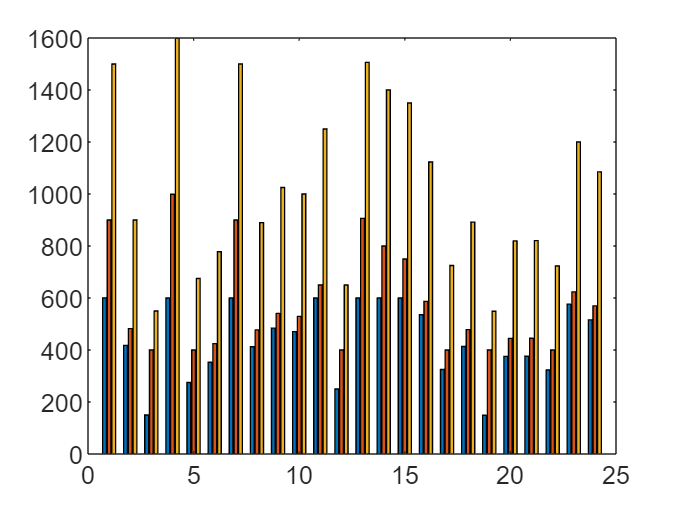

bar(SOLUCION )
% hold on
% stairs(x2)
% stairs(Pd,'-r')
xlim([0 25])